# EK 125 Project

**Group:**

- **Parker Dunn**

- **Brennan Lavoie**

- **Sam Yard**

clear all;
close all;

## Section: Introduction

Strokes are the 2nd leading cause of death globally, according to the World Health Organization (WHO). Over 10% of total deaths are the result of a stroke (Fedesoriano). The WHO has called the stroke, the ‘incoming epidemic of the 21st century’ (Sarikaya, Ferro & Arnold, 2015).  A stroke occurs when blood supply to part of the brain is cut off or reduced, preventing oxygen and nutrients from reaching brain cells. Without oxygen or nutrients brain cells begin to die after just minutes. Many strokes are preventable (Guzik & Bushnell, 2017). Some risk factors leaving one more susceptible to a stroke include hypertension (high blood pressure), smoking, diabetes mellitus (which results in elevated levels of blood glucose), a previous stroke, and obesity (Guzik & Bushnell, 2017). If there was a way to predict the likelihood of a patient developing a stroke, how many lives would we be able to save with effective medical interventions and/or lifestyle changes? Our selected dataset outlines this potentially relevant patient information to predict if a patient is more prone to have a stroke.

References

Fedesoriano (Ed.). (2021, January 26). Stroke prediction dataset. Retrieved April 04, 2021, from https://www.kaggle.com/fedesoriano/stroke-prediction-dataset

Guzik, A., & Bushnell, C. (2017). Stroke Epidemiology and Risk Factor Management. Continuum (Minneapolis, Minn.), 23(1, Cerebrovascular Disease), 15–39. https://doi.org/10.1212/CON.0000000000000416

Sarikaya, H., Ferro, J., & Arnold, M. (2015). Stroke prevention--medical and lifestyle measures. European neurology, 73(3-4), 150–157. https://doi.org/10.1159/000367652

## Function Overviews

#### Function: preview_data.m

- Purpose: This function extracts a set of fields and rows from the primary data structure, the table "strokedata," in order to display some part of the table.

- Syntax (for calling): *output_table = preview_data(entire_table, fieldslogical, rowselect, rowrange)*

- I wrote this function primarily to experiment with portions of the imported data.

- It didn't end up being very elaborate (in other words, the function is pretty short and maybe didn't warrant so much effort to be created), but some of the concepts can be reused for data extraction at other points.

- Inputs:

- (1) *entire_table* - used to pass in a table to extract from; set to simply take "strokedata" right now.

- (2) *fieldslogical* - In the script, there is space for someone to select which of the 12 fields from "strokedata" that they want to extract. That information is translated into a logical array that is passed into the function with this argument. In the function, this logical vector is used to extract the fields from the data table.

- (3) *rowselect* - passes in 1 or 2 to indicate whether all rows or a certain row range is desired from the "strokedata" table.

- (4) *rowrange* - a vector of the rows that you want to be extracted. This is only used if *rowselect = 2 *so the function knows to extract only some rows from the "strokedata" table.

- Output:

- *preview_table* - output is a subset of the "strokedata" table that was requested based on the inputs.

#### Function: bin_conditional_extract.m

- Purpose: To repetitively extract a set of rows from a field/column based on a condition in another field. The function should be able to extract data from certain subjects (i.e. rows) in a field of interest (the target field) based on the binary information in another field (conditional field).

- Syntax (for calling):

- ...to be continued

- Inputs:

- (1) *data_table* - the argument where the "strokedata" table is passed to the function

- (2) *targ_col* - the name or number of the field where the extracted data will come from

- (3) *cond_col* - the name or number of the field that will be used to determine if a row will be extracted

- (4) *condition* - must be a 1 or 0 (in the current configuration) and represents what elements should be extracted - e.g. condition == 1 ... then 1 must be in cond_col for the data in that row to be extracted.

- Outputs:

- (1) *extracted_data_array* - the function will extract data based on a binary condition and this vector will return the data from "targ_col"  for the rows with the correct binary condition in "cond_col".

- (2) *varargout *- THIS IS AN OPTIONAL OUTPUT. If the output is not requested with bracket notation, then it will not be returned by the function. If this output is requested, it returns the data that did not satisfy the condition provided to the function. Essentially, it is the data that was "ignored" when extracting "extracted_data_array".

## Section: Loading Data

### Importing the Data and Brief Overview of the Data

Loading in the "*healthcare-dataset-stroke-data.csv*" data.

Make sure to **(1)** have the CSV* file in the working directory* and **(2)** *match the file name* used above (or change it below) to ensure this code will load the data.

%This version of the "readtable" call only reads in a subset of the file
%{
Commented this out cause we don't really need it

strokedata_sample = readtable("healthcare-dataset-stroke-data.csv",'Range','A1:L5');

%}

%This version of the "readtable" call loads in the entire stroke dataet
strokedata = readtable("healthcare-dataset-stroke-data.csv");


A little overview of the information loaded in "strokedata"

Fields - *Total of 12*

- "id"                               - A list of integers to identify the patients

- "gender"                       - Male or Female

- "age"                            - Integers

- "hypertension"             - Binary

- "heart_disease"           - Binary

- "ever_married"             - Yes/No

- "work_type"                 - Categorical information - strings

- "Residence_type"        - Categorical (urban or rural)

- "avg_glucose_level"    - Float value

- "bmi"                            - Float, Int, or N/A

- "smoking_status"        - Categorical

- "stroke"                        - Binary

### **Setting up a short preview section, including a function that loads any choice of rows and fields.**

## *****No need to use this section unless you want to preview some of the raw data from the CSV file***

Select the fields you want - enter 1 to extract the field or 0 to ignore the field

id_f                =  0;
gender_f            =  0;
age_f               =  1;
hypertension_f      =  0;
heart_disease_f     =  0;
ever_married_f      =  0;
work_type_f         =  0;
Residence_type_f    =  0;
avg_glucose_level_f =  0;
bmi_f               =  1;
smoking_status_f    =  0;
stroke_f            =  1;

%creating the vector passed to the function preview_data
log_vec = logical([id_f, gender_f, age_f, hypertension_f,heart_disease_f, ever_married_f, work_type_f, Residence_type_f, avg_glucose_level_f,bmi_f, smoking_status_f, stroke_f]);


Select the rows you want.

There are **two approachs you can use to extract rows.**

(1) Select specific rows - *see bullet points below*

- Sections of rows can be passed via colon notation (e.g., 10:1:100)

- The rows will be extracted in numerical order - e.g. if [10, 2, 100, 2000, 60] are requested the rows will be returned in the order [2, 10, 60, 100, 2000].

(2) Select all rows

% Enter selected method for extracting rows
% "all rows" = 1
% "specific rows" = 2
choice = 2;

% Enter the specific rows you want below
rowrange = [1:10];  % enter the row numbers in the vector

preview_table = preview_data(strokedata,log_vec,choice,rowrange);
%struct displays below

% PREVIEW DISPLAYS HERE
disp(preview_table);

    age    bmi     stroke
    ___    ____    ______

    67     36.6      1   
    61      NaN      1   
    80     32.5      1   
    49     34.4      1   
    79       24      1   
    81       29      1   
    74     27.4      1   
    69     22.8      1   
    59      NaN      1   
    78     24.2      1   



% Just clearing up some memory.
% No need to keep these variables.
clearvars id_f gender_f age_f hypertension_f heart_disease_f ever_married_f work_type_f Residence_type_f avg_glucose_level_f bmi_f smoking_status_f stroke_f;
clearvars log_vec rowrange choice preview_table;

## **Section:**** Goals and Hypotheses**

The goal of our script is to identify the attributes that affect a person's risk of stroke. With that we can then focus on attempting to cluster the attributes to find the patients with these attributes that most effectively might yield a successful predictor of future strokes. Since strokes are preventable, the people who fit into a highly predictive cluster could be alerted that they are at a high risk for stroke. Then they could be informed of any preventative steps they could take to decrease this risk. Based on our preliminary research, we hypothesize that people who have any of the following are at a higher risk for stroke: history of hypertension or heart disease, a history of or a status of currently smoking, a high average glucose level and a high BMI. Furthermore, if they have more than one of these risk factors, then their risk for having a stroke increases even more. We will graph each of these risk factors individually to compare the number of patients who had a stroke with those who did not to be able to reinforce our preliminary research findings. We will then be able to use machine learning to pass these different attributes to the program which will return if it thinks that a person is likely to have a stroke or not. 

It is important to remember that only 249 patients in this study had a stroke, compared to the almost 5,000 who did not have a stroke, so coming to any significant conclusions based on this dataset might be hard. That is only a small percentage of patients who had a stroke. But we can compare the lifestyles of the patients within that group to try to come to conclusions about potential risk factors. 

## Section: Exploratory Data Analysis

## First, let's look at what portion of the patients in the study had a stroke or didn't have a stroke.

It is good sampling practice and good for predictive models to consider both people who did and did not have a stroke. Individuals who had a stroke provide insight into common lifestyle choices that may lead to strokes. Meanwhile, the subjects who did not have strokes offer a baseline of comparison. While we may find a common lifestyle choice among subjects who had a stroke, this factor may also be common among people who did not have a stroke (and generally common among the collective participants in the study). This comparison will be valuable in determining predictive factors for strokes.

Since it will be beneficial to compare the two groups of stroke patients, the distribution of these patients will be examined first.

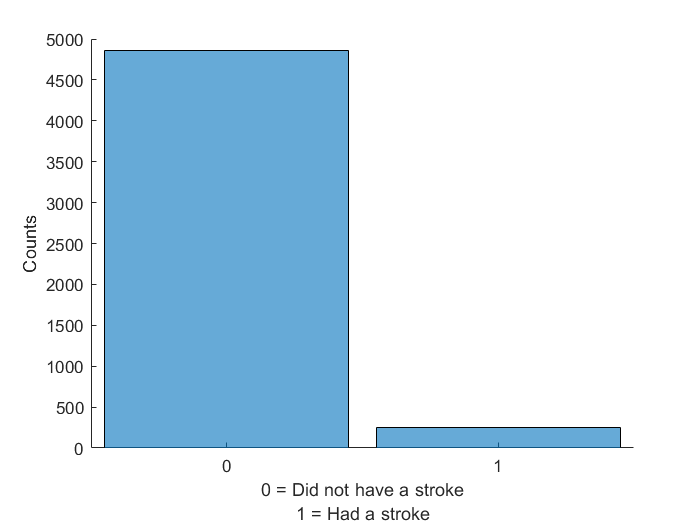

% Grabbing the "stroke" column of the table
stroke_col_array = strokedata.stroke;

stroke_dist_figure = figure(1);
clf(stroke_dist_figure)
hold on

stoke_dist = histogram(categorical(stroke_col_array),{'0','1'});
xlabel(["0 = Did not have a stroke","1 = Had a stroke"]);
ylabel("Counts")

hold off

% That count is really low. Determining the exact number of people who had
% a stroke
num_strokes = length(stroke_col_array(stroke_col_array == 1));
fprintf("There are %d individuals in the dataset who had a stroke.",num_strokes)

There are 249 individuals in the dataset who had a stroke.

clearvars num_strokes stroke_col_array

Clearly, more patients were surveyed for this study that did not have a stroke compared to the small group of 249 poeple that did have a stroke. The sample size of patients with a history of stroke is small compared to the entire collection of people interviewed, which limits, to some degree, the value of any conclusions about strokes that we may develop from this data. The sample is probably a bit small to be able to generate robust predictions about a perosn's chances of having a s.troke. However, the primary focus here is to identify lifestyle features that correlate with risk of stroke. The large sample size of non-stroke patients means that any risk factor or lifestyle choice that clearly distinguishes the group of patients with a stroke from the rest of the patients is highly likely to be predictive of a stroke.

## Second, basic statistics about **gender**. Only one piece of information is available: how many males and how many females.

% Gotta grab the only information about gender.
gender_array = strokedata.gender;

% Determining all of the unique entries in this data
entry_types = unique(gender_array)

entry_types = 3×1 cell array
    {'Female'}
    {'Male'  }
    {'Other' }


% Now that we know what we are looking at, let's get a distribution of
% these entries
gender_categories = categorical({'Female','Male','Other'});
sort_gender_categories = reordercats(gender_categories,{'Female','Male','Other'});

These two lines are kind of fomatting related for the categories. More info here: [https://www.mathworks.com/help/matlab/ref/bar.html](https://www.mathworks.com/help/matlab/ref/bar.html)

Also, below I used a function that automatically counts categorical information -- "histcounts"

Information about histcounts can be found at: [https://www.mathworks.com/help/matlab/ref/histcounts.html](https://www.mathworks.com/help/matlab/ref/histcounts.html)

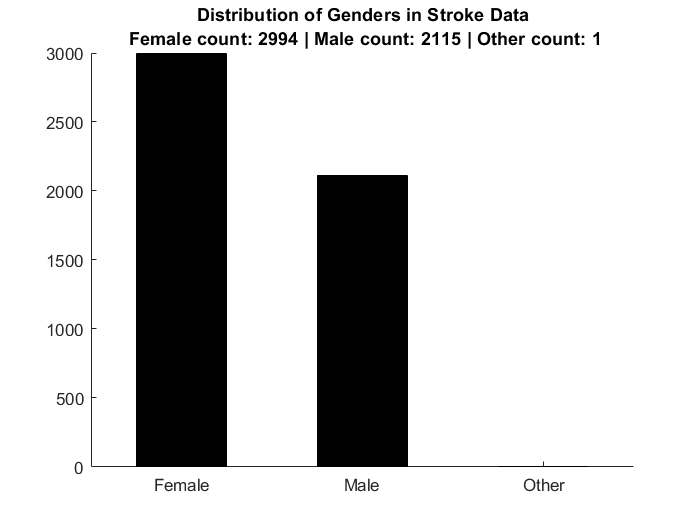

gender_dist_plot = figure(2);
clf(gender_dist_plot) %note: this just clears the figure so changes can be made and the old ones will disappear.
hold on
% grabbing the plotting values
gender_dist = histcounts(categorical(gender_array),sort_gender_categories);
%plotting the information
bar(sort_gender_categories,gender_dist,0.5,'k');
%interesting title for the plot
gender_plot_title = sprintf("Distribution of Genders in Stroke Data\n Female count: %d | Male count: %d | Other count: %d",...
                            gender_dist(1),gender_dist(2),gender_dist(3));
title(gender_plot_title);
hold off

clearvars gender_plot_title gender_dist gender_categories sort_gender_categories entry_types; % freeing up some computer space

This shows that females are more likely to have a stroke. But why that is we cannot deduce based on the information we have available.  

## Third, basic statistics about age. Let's do some binning and look at the distribution.

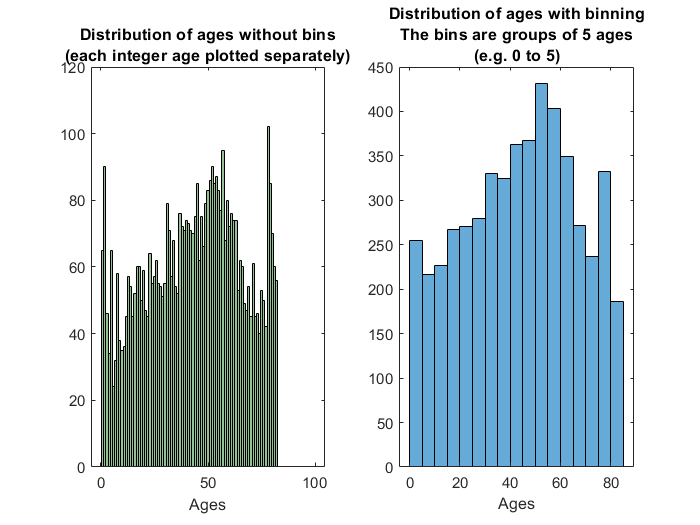

%grabbing the age data
age_array = strokedata.age;

%Going to do a subplot
% Subplot 1: All ages ... no binning
% Subplot 2: All ages ... binned within a range
%   (ex. bins of 5 years, 21-25 | 26-30 | 31-35 etc.)

age_distribution_plot = figure(3);
clf(age_distribution_plot)

hold on
subplot(1,2,1);
% PLOT 1 Script 
no_bins_edges = [0.5:1:99.5]; %Should indicate to "histogram" function what values we want in these bins.
age_no_bins_hist = histogram(age_array,no_bins_edges,'FaceColor',[0.3, .6, 0.3]);
%Modifying histogram
titleforsubplot1 = sprintf("Distribution of ages without bins\n(each integer age plotted separately)");
title(titleforsubplot1);
xlabel("Ages");

%PLOT 2 Script
subplot(1,2,2);
%going to use features of "historgram" function to do binning
age_bins_hist = histogram(age_array,'BinMethod','auto');

titleforsubplot2 = sprintf("Distribution of ages with binning\nThe bins are groups of %d ages\n(e.g. %d to %d)",...
                             (age_bins_hist.BinEdges(2)-age_bins_hist.BinEdges(1)),...
                              age_bins_hist.BinEdges(1), age_bins_hist.BinEdges(2));
title(titleforsubplot2)
xlabel("Ages")

hold off

clearvars age_no_bins_hist titleforsubplot1 titleforsubplot1 no_bins_edges ages_no_stroke ages_no_stroke_pats ages_stroke_patients 
clearvars ages_distribution_plot ages_distribution_stroke_conditional; %freeing up computer space

The age distributions reveal some deviations from a normal data distrbitution. Age does not seem like a feature that would generally follow a normal distribution, but it's still important to keep of the trends in this data among the subjects.

In particular, it is interesting that the distribution of all ages has large spikes at very high and very low ages. The age 1 bin has nearly 100 subjects from the study. The study was conducted among patients in a hospital, so seeing 100 babies in a hospital is not unexpected since they likely make far more visits to doctors than the average healthy adult, but this group may need to be separated out when it comes to using this data for predicting strokes. **It is unlikely that babies and young children can effectively provide information about predicting the potential for a stroke.**

***Next, we will extract the number of patients who have hypertension and look to see how many of them also had a stroke. ***

% Exploring the distribution of patients who had a stroke and hypertension

hypertension_mask = (strokedata.hypertension == 1);         % Extract a logical of patients who had a stroke
count_hypertension = sum(hypertension_mask);                % total number of people who had a stroke
hypertension_positive  = strokedata(hypertension_mask,:);   % table including only patients who have hypertension
stroke_mask = (hypertension_positive.stroke==1);            % Further extracting parts of the table: patients who have hypertension and had a stroke!
count_stroke = sum(stroke_mask);


percent_hypertension_stroke = (count_stroke/count_hypertension)*100;

fprintf("There were %d particiants who have a history of hypertension and %d of them also suffered a stroke.\n", count_hypertension, count_stroke);

There were 498 particiants who have a history of hypertension and 66 of them also suffered a stroke.


fprintf("This means that %.2f%% of the participants who have hypertension also suffered a stroke.\n", percent_hypertension_stroke);

This means that 13.25% of the participants who have hypertension also suffered a stroke.


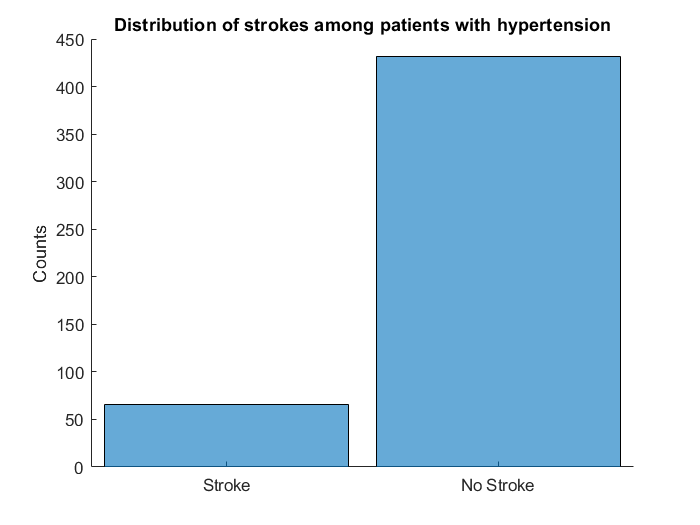

y1 = count_stroke;
y2 = count_hypertension - count_stroke;
figure(21);
clf(21);
hold on


histogram('Categories',{'Stroke','No Stroke'},'BinCounts',[y1, y2])
title("Distribution of strokes among patients with hypertension")
ylabel("Counts")

hold off

This data is simply meant to help demonstrate the distribution of patients with hypertension. There are significantly more patients who did not have a stroke than who did, so it is not surprising to see far more non-stroke patients with hypertension. Therea are two helpful observations that you can make from this data though. First, a relatively low number of patients (only around 10%) reported having hypertension. Second, while the number of stroke patients with hypertension is a low total, more than 20% of the stroke patients had hypertension. It is not definitive information, but there does appear to be a higher rate of hypertension among the stroke patients (more than 20%) compared to the general collection of patients (about 10%).

***Now, we will extract the number of patients who have a history of heart disease and look to see how many of them also had a stroke.***


heart_mask = strokedata.heart_disease == 1;
count_heart = sum(heart_mask);
heart_positive  = strokedata(heart_mask,:);
heart_mask = heart_positive.stroke==1;
count_heart_stroke = sum(heart_mask);


percent_heart_disease_stroke = (count_heart_stroke/count_heart)*100;

fprintf("There were %d particiants have a history of heart disease and %d of them also suffered a stroke.\n", count_heart, count_heart_stroke);

There were 276 particiants have a history of heart disease and 47 of them also suffered a stroke.


fprintf("This means that %.2f%% of the participants who have hypertension also suffered a stroke.\n", percent_heart_disease_stroke);

This means that 17.03% of the participants who have hypertension also suffered a stroke.


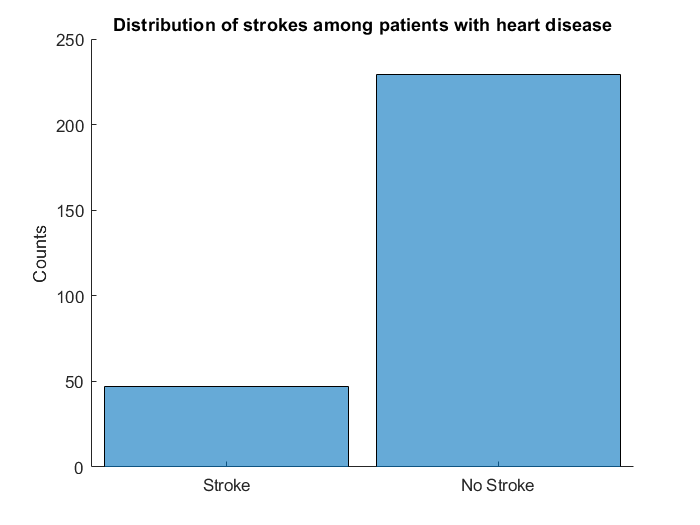


yhd1 = count_heart_stroke;
yhd2 = count_heart - count_heart_stroke;

figure(22);
clf(22);
hold on

histogram('Categories',{'Stroke','No Stroke'},'BinCounts',[yhd1, yhd2])
title("Distribution of strokes among patients with heart disease")
ylabel("Counts")

hold off

clearvars count_heart count_heart_stroke heart_mask heart_positive

This data is simply meant to help demonstrate the distribution of patients with heart disease. There are significantly more patients who did not have a stroke than who did, so it is not surprising to see far more non-stroke patients with heart disease. There are helpful observations that you can make from this data though. First, a relatively low number of patients (only around 5%) reported having heart disease. Second, while the number of stroke patients with heart disease is a low total, more than about 20% of the stroke patients had heart disease. It is not definitive information, but there does appear to be a higher rate of heart disease among the stroke patients.

***We will now compare the number of strokes seen in patients who have a history of smoking/are currently smoking with the number of strokes seen in patients that never smoked. ***

smoking_col_from_table = strokedata.smoking_status;
smoking_array_entries = unique(smoking_col_from_table) % just returns all the categories that we are looking for

smoking_array_entries = 4×1 cell array
    {'Unknown'        }
    {'formerly smoked'}
    {'never smoked'   }
    {'smokes'         }


[counts, order_of_counts] = histcounts(categorical(smoking_col_from_table),smoking_array_entries);

Counts is the number of appearances of each of the categories in "smoking_array_entries"

"Order_of_counts" should contain the same information as "smoking_array_entries", but is ordered to match the counts in the "Counts element"

for i = 1:length(counts)
    fprintf("%s: %d counts\n",order_of_counts{i},counts(i))
end

Unknown: 1544 counts
formerly smoked: 885 counts
never smoked: 1892 counts
smokes: 789 counts


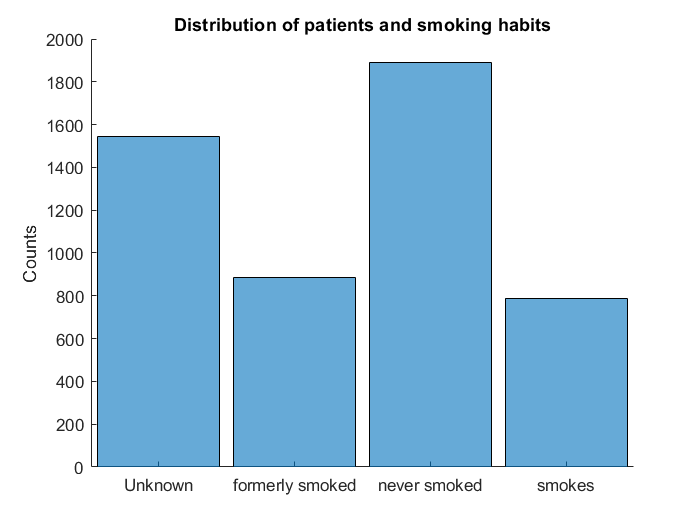

figure(23);
clf(23);
hold on
histogram('Categories',order_of_counts,'BinCounts',counts)
title("Distribution of patients and smoking habits")
ylabel("Counts")
hold off

[smoking_col_stroke_pos, smoking_col_stroke_neg] = bin_conditional_extract(strokedata,"smoking_status","stroke",1);

[counts2, order_of_counts2] = histcounts(categorical(smoking_col_stroke_pos),smoking_array_entries);
[counts3, order_of_counts3] = histcounts(categorical(smoking_col_stroke_neg),smoking_array_entries);

fprintf("There were %d particiants who formerly or currently smoke and %d of them also suffered a stroke.\n", counts(2) + counts(4), counts2(2) + counts2(4));

There were 1674 particiants who formerly or currently smoke and 112 of them also suffered a stroke.


fprintf("This means that %.2f%% of the participants who have formerly or currrently smoked also suffered a stroke.\n",...
                                                                       (counts2(2) + counts2(4))/ (counts(2) + counts(4))*100);

This means that 6.69% of the participants who have formerly or currrently smoked also suffered a stroke.


fprintf("There were %d particiants who never smoked and %d of them also suffered a stroke./n", counts(3), counts2(3));

There were 1892 particiants who never smoked and 90 of them also suffered a stroke./n

fprintf("This means that %.2f%% of the participants who have never smoked also suffered a stroke./n", (counts2(3)/counts(3)) * 100);

This means that 4.76% of the participants who have never smoked also suffered a stroke./n

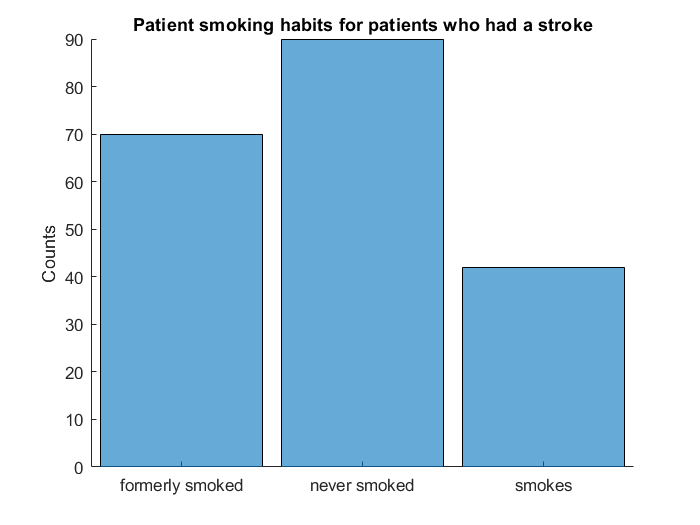


%Now, here is the information plotted

smoking_and_stroke_1 = figure(24);
%smoking_and_stroke_subplot.Position = [800 500 560 420] --- Ignore this
clf(24);
hold on
histogram('Categories',order_of_counts2(2:4),'BinCounts',counts2(2:4))
title("Patient smoking habits for patients who had a stroke")
ylabel("Counts")
hold off

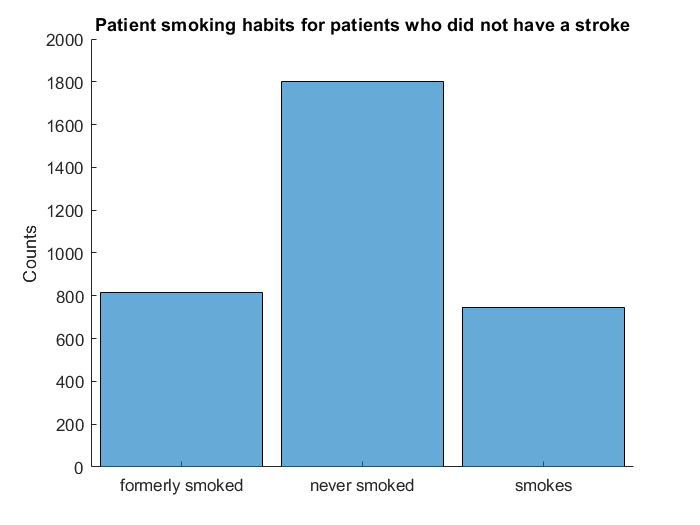

smoking_and_stroke_2 = figure(25);
clf(25);
hold on
histogram('Categories',order_of_counts3(2:4),'BinCounts',counts3(2:4))
title("Patient smoking habits for patients who did not have a stroke")
ylabel("Counts")
hold off

formated_print = "Among stroke patients, %d patients of %d total are smokers (%.2f%%).\n\nAmong non-stroke patients, %d patients of %d total are non-smokers (%.2f%%).\n\nNote: These numbers include those patients who reported as being 'unknown'.";
fprintf(formated_print,counts2(2) + counts2(4), sum(counts2), sum(counts2([2,3]))/sum(counts2)*100,counts3(2) + counts3(4), sum(counts3), sum(counts3([2,3]))/sum(counts3)*100)

Among stroke patients, 112 patients of 249 total are smokers (64.26%).

Among non-stroke patients, 1562 patients of 4861 total are non-smokers (53.84%).

Note: These numbers include those patients who reported as being 'unknown'.

                                
clearvars smoking_array_entries percent_heart_disease_stroke title_subplot2 titleforsubplot2 title_subplot1 stroke_dist stroke_mask formated_print counts counts2 counts3
clearvars order_of_counts order_of_counts2 order_of_counts3 smoking_col_from_table smoking_col_stroke_neg smoking_col_stroke_pos

An initial observation about this data is the large number of unknown entries among the patients. More than 20% of the participants are listed as "unknown," which makes it challenging to use this attribute of the data to make predictions about a person's chance of stroke.

Ideally, the data could be used without any of these subjects. However, the smoking patients available are already a small portion of the data, and their other data is valuable. *While performing some data cleaning before proceeding to analysis, some of the "unknown" subjects may be removed, but these individuals were generally treated as "never smoking."* This decision errors on the side of indicating that smoking is not a factor that leads to strokes; a conclusion drawn based on the distributions of stroke and non-stroke patients (above), where the proportion of non-smokers is much higher among the patients who have not had a stroke.

Additionally, there does not appear to be a significant variation in smoking patterns in the distributions of stroke patients and non-stroke patients. The relationships of the smokers ("formerly smoked" and "smokes") and non-smokers ("never smoked") in the plot above are not exactly identical, which would indicate no difference at all. The total counts of smokers and non-smokers is approximately equal among the samples of stroke and non-stroke patients. As a model is developed to predict the chance of someone having a stroke, the model will be given this data, and it will be allowed to learn to use this information appropriately even if it turns out that the smoking data does not have a significant impact on its ability to predict that someone is likely to have a stroke.

### ***EDA Continues - Distribution of average glucose level among the study patients***

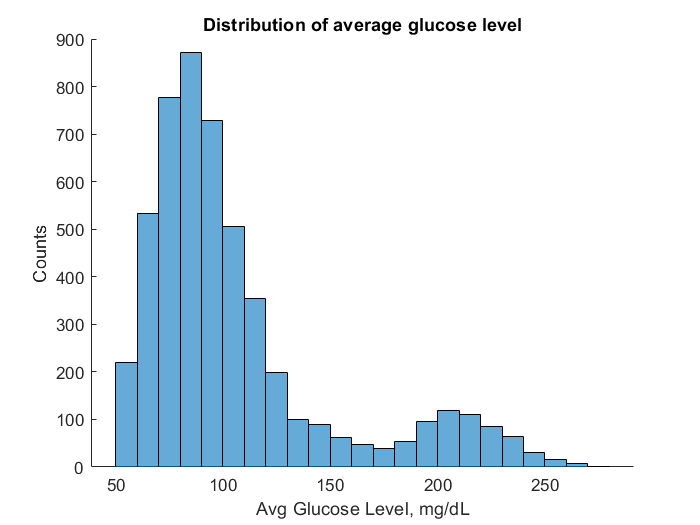

f1 = figure(27);
clf(f1);
hold on
histogram(strokedata.avg_glucose_level,'BinMethod',"auto");

title("Distribution of average glucose level")
xlabel("Avg Glucose Level, mg/dL")
ylabel("Counts")
hold off

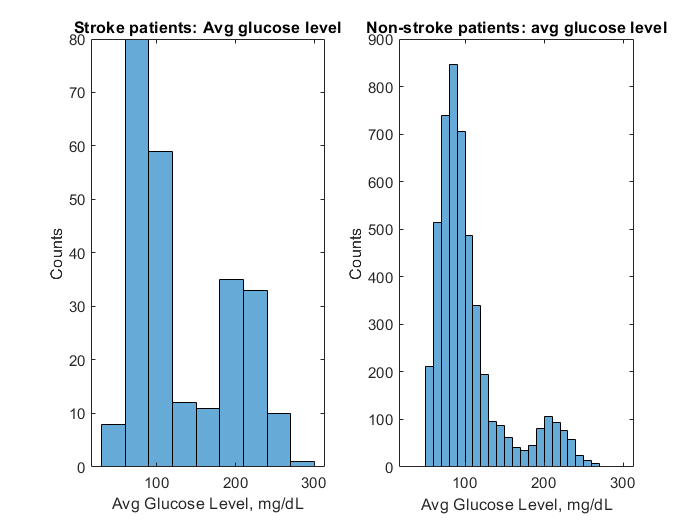


[avg_glucose_stroke, avg_glucose_no_stroke] = bin_conditional_extract(strokedata,"avg_glucose_level","stroke",1);
f2 = figure(28);
clf(f2);
hold on

subplot(1,2,1)
h1 = histogram(avg_glucose_stroke,'BinMethod',"auto");
title("Stroke patients: Avg glucose level")
xlabel("Avg Glucose Level, mg/dL")
ylabel("Counts")

subplot(1,2,2)
h2 = histogram(avg_glucose_no_stroke,'BinMethod',"auto");
h2.BinLimits = [30, 300];
title("Non-stroke patients: avg glucose level")
xlabel("Avg Glucose Level, mg/dL")
ylabel("Counts")

clearvars f1 f2 h1 h2 avg_glucose_no_stroke avg_glucose_stroke;

*****Observations related to the AVG GLUCOSE LEVEL go here.*****

### ***EDA Continues - Distribution of BMI among the study patients***

*(5) BMI - a historgram distribution of with the average glucose levels binned (like the age distribution)*

*Context:*

- *We may want to include information on the BMI ranges - what numbers are placed into each category I mean*

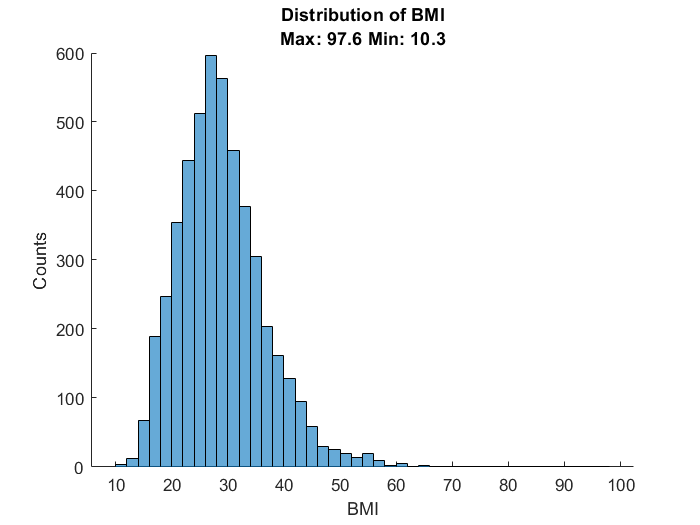

f1 = figure(30);
clf(f1);
hold on
histogram(strokedata.bmi,'BinMethod',"auto");
titlef1 = sprintf("Distribution of BMI\nMax: %.1f Min: %.1f",max(strokedata.bmi),min(strokedata.bmi));
title(titlef1)
xlabel("BMI")
ylabel("Counts")
hold off

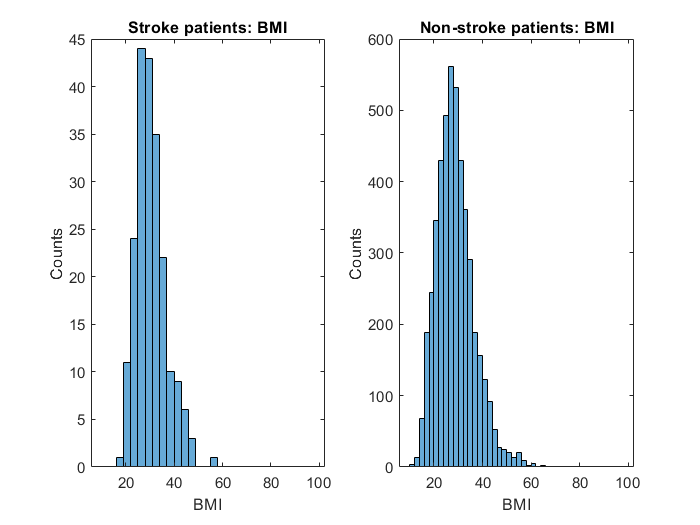

[bmi_stroke, bmi_no_stroke] = bin_conditional_extract(strokedata,"bmi","stroke",1);
f2 = figure(31);
clf(f2);
hold on

subplot(1,2,1)
h1 = histogram(bmi_stroke,'BinMethod',"auto");
h1.BinLimits = [10,98];
title("Stroke patients: BMI")
xlabel("BMI")
ylabel("Counts")

subplot(1,2,2)
h2 = histogram(bmi_no_stroke,'BinMethod',"auto");
title("Non-stroke patients: BMI")
xlabel("BMI")
ylabel("Counts")


clearvars f1 titlef1 f2 h2 h1;

For the BMI data, there does not appear to be much of a shift in the distribution

***"These features show/did not show there is or is not a correlation between strokes."***

## **Section:**** Data Scrubbing and Preparation**

In the Data Analysis section below, some preliminary analysis has indicated that extracting only adults from "strokedata" will yield more accurate information about people who are at risk for strokes. The section of code below will be used to extract a table of only patients above the age of 18 that can be used for the majority of our data analysis.

strokedata_18plus = strokedata([strokedata.age >= 18],["gender","age","hypertension","heart_disease","work_type",...
                                                       "Residence_type","avg_glucose_level","bmi","smoking_status","stroke"]);
%NOTE: Some variables from "strokedata" were removed.
% "id" & "ever_married" were not extracted


From the preliminary exploration of the data, most attributes provided on the patients in this study did not provide a strong basis to extract the stroke patients. In other words, when separating the stroke patients from non-stroke patients in EDA, very few of the attributes extracted a significant portion of the 249 stroke patients while extracting very few of the non-stroke patients. In particular, three commonly linked risk factors for health complications, (1) heart disease, (2) hypertension, and (3) smoking did not show an obvious percentage increase in the stroke patients compared to the overall patient sample. As noted with hypertension in particular, there might be a slight, and still useful, shift caused by these risk factors. Thus, some feature engineering was done to translate these binary pieces of information ("smoking status" was translated to two groups: (1) smoked at any point and (2) never smoked at all or unknown) to a four point scale that generally represents medical risk factors for the patients in the study.

In the section below, the three features "heart_disease", "hypertension", and "smoking_status" were redesigned to fit on a four point scale. The four point scale was added back to the table to replace these three attributes in a new attribute that was named "medical_risk." A short outline of what was done is provided below before the new feature was created.

- No risk factors (i.e. not a smoker, no heart diseas, and no hypertension) === 0

- 1 risk factor     === 1

- 2 risk factors   === 2

- All risk factors === 3

The model was passed only the "medical_risk" attribute, not any of the three attributes that contribute to it, with the idea that the group of information is likely a better predictor of stroke than any of the individual attributes. While MATLAB's machine learning model may have been able to come to the same conclusion or may have come to a slightly different conclusion, this approach seemed to be the most tangible and informative all in one.

%starting with the data table created above --- strokedata_18plus

%Going to remove "Residence_type" now because it has not been an attribute
%that we are interested in (will remove by not extracting through really

%Using a function to perform the feature creation and preparation of a new
%table because I did not want to clutter this script more than necessary

%INPUTS: strokedata_18plus
strokedata_prepped = datacleanandprep(strokedata_18plus);


The new table "strokedata_prepped" has 7 columns. These columns are listed below.

- "gender"

- "age"

- "Work_type"

- "avg_glucose_level"

- "bmi"

- "stroke"

- "medical_risk"

These attributes will be provided to the classification learner in MATLAB in order to develop a model that accurately predicts stroke from this information. The "stroke" column of the table will the response that the model is trying to classify. It will be using the other 6 features provided as predictors that classify subjects as likely or not to have a stroke.

## **Section:**** Data Analysis**

***Tasks for Data Analysis***

- ***MAJOR TASK: use some ML ... lmao ... no idea how yet***

- ***(1) *****Probably not enough time to thoroughly do this but* ****Supplement Machine learning predcitions with an attempt to find a cluster of risk factors that highly correlate with risk of stroke***

                *This would require extracting only patients with certain risk factors (Example: hypertension, high BMI, and a history of smoking) then determine if there significant difference in the distributions of*

*                the data.*

- ***(2) ... that's probably enough right? ... nothing more for now!!! (We can do this thing!)***

#### Further exploration of age distribution based on other qualifying factors.

Age is an important qualifier in the context of lifestyle choices effecting a person's chances of having a stroke. It is likely at younger ages that strokes are frequently a result of other medical conditions rather than a child's lifestyle choices, which is what we are generally considering with this dataset. Similarly, elderly subjects in the study are more likely to have additional medical conditions that may play a role in their chances of having a stroke. The next step was to briefly investigate the age distributions of certain attributes (like whether or not someone had a stroke) based on ages.

% This line uses "bin_conditional_extract" (read: "Binary Conditional
% Extract") to extract the ages (in a vector) of people who had a stroke
[ages_with_stroke, ages_no_stroke] = bin_conditional_extract(strokedata,"age","stroke",1);


Now that the ages have been separated into two groups, it is time to look at how ages are distributed for stroke patients compared to non-stroke patients.

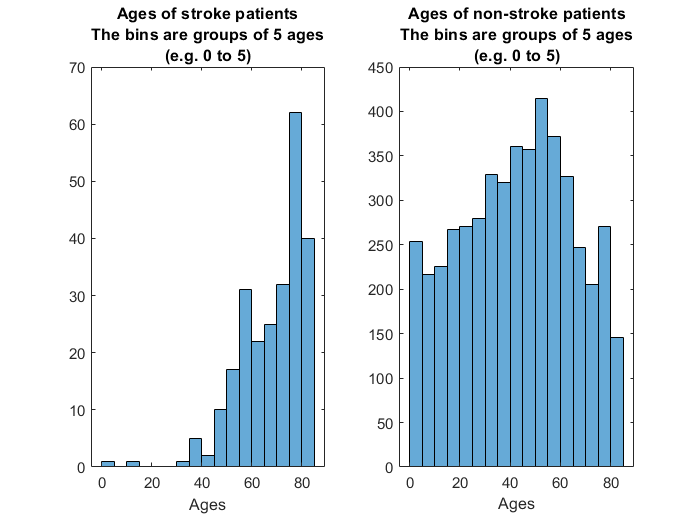

age_distribution_stroke_conditional = figure(20); %20 is a random figure number
clf(age_distribution_stroke_conditional)

subplot(1,2,1)
%going to use features of "historgram" function to do binning
ages_stroke_patients = histogram(ages_with_stroke,'BinMethod','auto');

title_subplot1 = sprintf("Ages of stroke patients\nThe bins are groups of %d ages\n(e.g. %d to %d)",...
                             (ages_stroke_patients.BinEdges(2)-ages_stroke_patients.BinEdges(1)),...
                              ages_stroke_patients.BinEdges(1), ages_stroke_patients.BinEdges(2));
title(title_subplot1)
xlabel("Ages")


subplot(1,2,2)
ages_no_stroke_pats = histogram(ages_no_stroke,'BinMethod','auto');

title_subplot2 = sprintf("Ages of non-stroke patients\nThe bins are groups of %d ages\n(e.g. %d to %d)",...
                           (ages_no_stroke_pats.BinEdges(2)-ages_no_stroke_pats.BinEdges(1)),...
                           ages_no_stroke_pats.BinEdges(1), ages_no_stroke_pats.BinEdges(2));
title(title_subplot2)
xlabel("Ages")

hold off

Based on the plots above, it certainly looks like there is a correlation between age and a person's chances of having a stroke. This is useful information with regard to our end goal, understanding what risk factors can be used to predict a person's chances of having a stroke, and will come up later as we try to find a way to predict a person's chances of having a stroke.

However, most importantly, this age information provides some valuable underlying context to the rest of our data analysis: young children and babies, who do not have useful inputs for many of the attributes investigated (like smoking status, BMI, hypertension, etc.), probably do not contribute helpful information about how these risk factors effect a person's chances of having a stroke. **Moving forward, it will likely be helpful to look at only patients in the age range 18+ becasue they are full grown adults that are more responsible for their lifestyle choices and accurate information about the relationships between the risk factors and stroke rates. The patients under 18 perhaps suffered a stroke due to other issues unrelated to lifestyle, such as other illnesses or having the genetic tendency for a stroke.**

Before proceeding to remove a set of ages in the data, a test of significance was done on the two distributions above to test our hypothesis that the distribution of ages among stroke patients is signficantly different than distribution of all patients in the study. 

In other words,

- A two sample t-test was done to determine if the two populations in the plot above represent the same normal distribution of people (Null hypothesis). Alternatively, if there is a significant difference between the distributions, then the test will indicate that there is a signficant difference in the data sets, which are soley different based on the condition that one group is former stoke patients.

- Null hypothesis (returns 0 for no significant difference): The two distributions are from the same population of people. In other words, the fact that one group is only stroke patients does not significantly effect the distribution of ages.

[h, p] = ttest2(ages_with_stroke,ages_no_stroke);
fprintf("The t-test returned h = %d. The chance that these distributions represent the same populations of ages is %.3f%%.\n",h,p*100)

The t-test returned h = 1. The chance that these distributions represent the same populations of ages is 0.000%.


The test supports the conclusion that stroke patients have a signficantly different age distribution, which can be seen graphically as being higher ages among stroke patients. Now, the stroke data will be re-extracted but will only consider patients who are 18+ in age.

clearvars ages_no_stroke ages_with_stroke; %clearing some space first


**NOTE:** The 18+ patients were extracted into a new table to use for data analysis in the Data Scrubbing and Extraction section above.

The 18+ patients have been extracted to **"strokedata_18plus."**

Now, the age distributions will be displayed briefly for the new data.

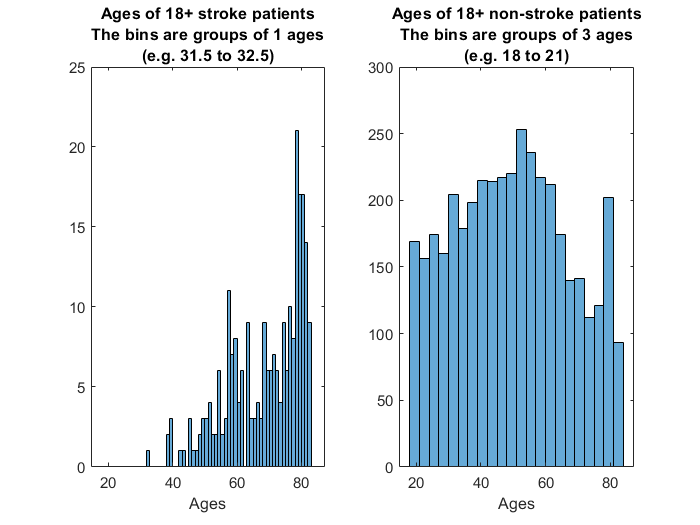

[ages_stroke, ages_no_stroke] = bin_conditional_extract(strokedata_18plus,"age","stroke",1);

age_distribution_stroke_conditional = figure(26); %26 is a random figure number
clf(age_distribution_stroke_conditional)

subplot(1,2,1)
%going to use features of "historgram" function to do binning
ages_stroke_patients = histogram(ages_stroke,'BinMethod','auto');

title_subplot1 = sprintf("Ages of 18+ stroke patients\nThe bins are groups of %d ages\n(e.g. %.1f to %.1f)",...
                             (ages_stroke_patients.BinEdges(2)-ages_stroke_patients.BinEdges(1)),...
                              ages_stroke_patients.BinEdges(1), ages_stroke_patients.BinEdges(2));
title(title_subplot1)
ages_stroke_patients.BinLimits = [18, 84];
xlabel("Ages")



subplot(1,2,2)
ages_no_stroke_pats = histogram(ages_no_stroke,'BinMethod','auto');

title_subplot2 = sprintf("Ages of 18+ non-stroke patients\nThe bins are groups of %d ages\n(e.g. %d to %d)",...
                           (ages_no_stroke_pats.BinEdges(2)-ages_no_stroke_pats.BinEdges(1)),...
                           ages_no_stroke_pats.BinEdges(1), ages_no_stroke_pats.BinEdges(2));
title(title_subplot2)
ages_no_stroke_pats.BinLimits = [18, 84];
xlabel("Ages")

hold off


clearvars ages_stroke ages_no_stroke;

### Data Analysis: Using the Classification Learner to Develop a Stroke Prediction Model

At this point, the strokedata_prepped table was used to develop a machine learning model. The entire table was passed to the application. This was done with the knowledge that the application is capable of performing a self assessement of itself. The model application was instructed to separate off 10% of the data in "strokedata_prepped" to use as an assessment tool. As models were developed, this randomly separated data was used to assess the accuracy of each model iteration.